# Processing Event 2: 1 March 2011


% Initializing path of HDF5 file
clear all;
pfisrExpFileName = '20080215.005_bc_2min-Ne-cal.h5';
dascDateStr = '15 Feb 2008';
minTimeStr = '16 Feb 2008 10:00';
maxTimeStr = '16 Feb 2008 13:00';
thisTimeStr = '16 Feb 2008 11:10';

## PFISR Data

rootpath= 'G:\My Drive\Research\Projects\Paper 2\Data\Madrigal Events\'; 
fileNameStr = [rootpath,pfisrExpFileName];


## Download FITS DASC data

download_DASC_FITS(dascDateStr);

## Extracting data

amisrData=read_amisr(fileNameStr);

## Creating magnetic field aligned coordinates

amisrData = aer_to_field_aligned_cartesian(amisrData,70);

## Interpolating data to field aligned coordinates

[amisrData] = interpolate_to_field_aligned_coords(amisrData,minTimeStr,maxTimeStr);
%% need to think more about this interpolation

## Creating Energy Spectra

[dataInv,magcoords,dataInputInv] = get_2D_energy_spectra(amisrData,logspace(3,6,30)',...
    minTimeStr,maxTimeStr,[60 200],'magnetic');

avg.MSE = 6.1687 avg.iterno = 6650.1149


## Plot Energy Spectra

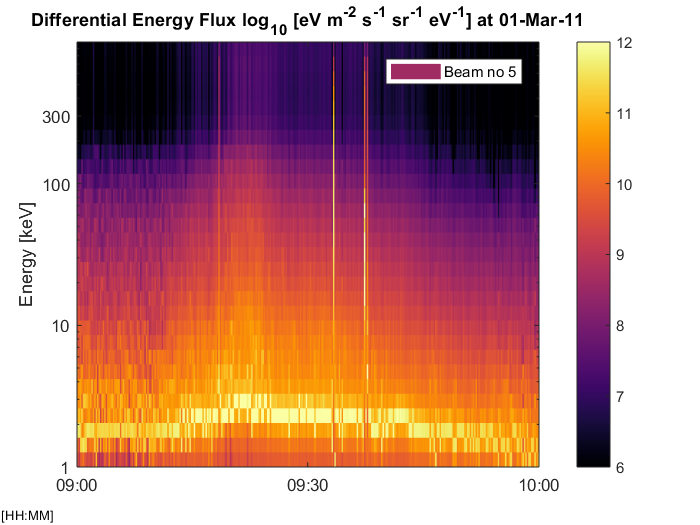

avgEnergyFlux = zeros(size(dataInv(1).energyFlux));
for iBeam = 1:1:amisrData.nBeams
    avgEnergyFlux = avgEnergyFlux + dataInv(iBeam).energyFlux;
end
avgEnergyFlux=avgEnergyFlux/amisrData.nBeams;

figure;
colormap(inferno);
plot_2D_time_series(dataInv(iBeam).time(1,:),dataInv(iBeam).energyBin/1000,log10(dataInv(iBeam).energyFlux),1/2,3);
caxis([6 12]);
colorbar;
ylabel('Energy [keV]');
set(gca,'YTick',[1,10,100,300]);
legend(['Beam no ',num2str(iBeam)]);

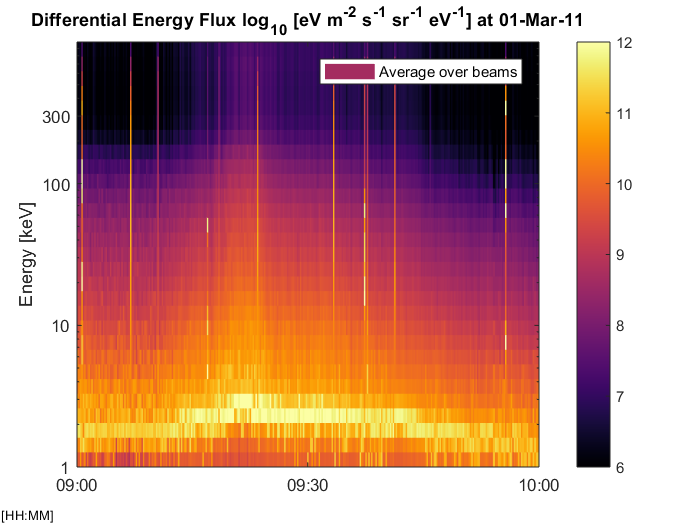


figure;
colormap(inferno);
plot_2D_time_series(dataInv(iBeam).time(1,:),dataInv(iBeam).energyBin/1000,log10(avgEnergyFlux),1/2,3);
caxis([6 12]);
colorbar;
ylabel('Energy [keV]');
set(gca,'YTick',[1,10,100,300]);
legend('Average over beams');

## Plot 2D energy flux maps

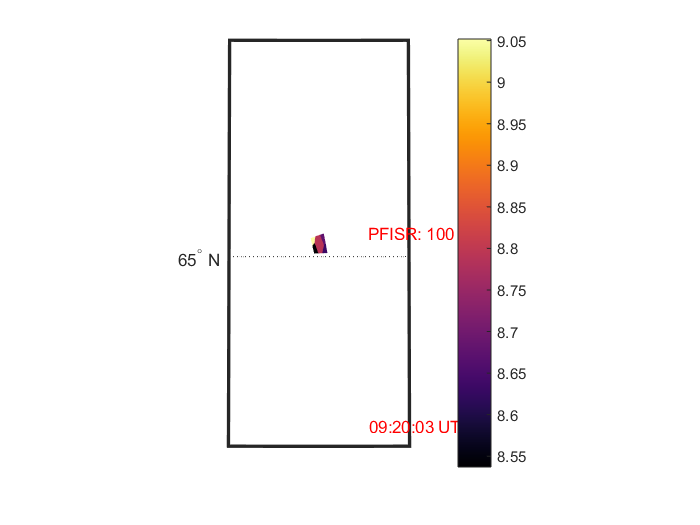

timeNo = find_time(dataInv(1).time,thisTimeStr);
figure;colormap(inferno);
plot_2D_energy_slice_geodetic_v1(dataInv,amisrData,magcoords,energyBin,nBeams,timeNo,110,100);
colorbar;

## Plot DASC data

ASIfileStr=get_DASC_filename([initialize_root_path,'LargeFiles\DASC\',datestr(dascDateStr,'yyyymmdd')],thisTimeStr);
azStr=[initialize_root_path,'LargeFiles\DASC\26Mar2008\','PKR_Cal_before_2011\PKR_20111006_AZ_10deg.FITS'];
elStr=[initialize_root_path,'LargeFiles\DASC\26Mar2008\','PKR_Cal_before_2011\PKR_20111006_EL_10deg.FITS'];
    azOldRes=fitsread(azStr);
    elOldRes=fitsread(elStr);
[ASI.dataNew, ASI.lat, ASI.lon, ASI.az_new, ASI.el_new, ASI.sensorloc, ASI.timeDASC] = DASC_aer_to_geodetic...
(char(ASIfileStr), azOldRes, elOldRes,512, 30, 110);

Folders added to the path:
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Main'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Reading'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Utilities'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Utilities\Coordinate_Transforms'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Utilities\General_Tools'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Utilities\Plotting'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Utilities\Struct_Functions'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\Utilities\Time'
    'C:\Users\nithin\Documents\GitHub\energy-height-conversion\GeoDataMATLAB\logo'



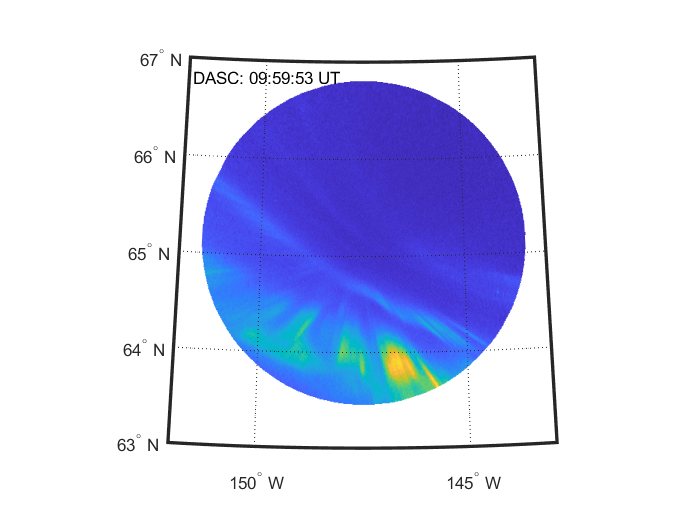

figure;
plot_DASC_geodetic(ASI.dataNew, ASI.timeDASC, ASI.lat, ASI.lon, 512, [63 67], [-152 -143]);

## Plot combined DASC and Energy Spectra

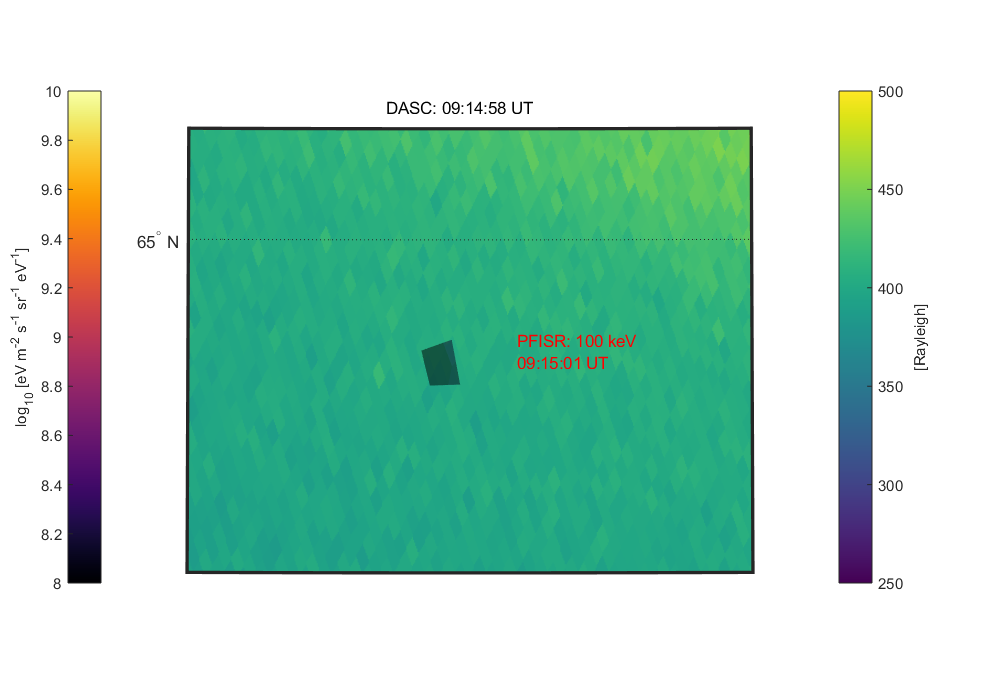

dirName = [initialize_root_path,'LargeFiles\DASC\',datestr(dascDateStr,'yyyymmdd')];
azStr=[initialize_root_path,'LargeFiles\DASC\26Mar2008\','PKR_Cal_before_2011\PKR_20111006_AZ_10deg.FITS'];
elStr=[initialize_root_path,'LargeFiles\DASC\26Mar2008\','PKR_Cal_before_2011\PKR_20111006_EL_10deg.FITS'];
DASCcalFile.az = azStr; DASCcalFile.el = elStr; 
figure1 = figure; 
    plot_2D_energy_slice_with_DASC(figure1,thisTimeStr,...
    dataInv,amisrData,magcoords,DASCcalFile,...
    dirName,[64.85 65.05],[-147.95 -147.35]);

## Creating images and store

dirName = [initialize_root_path,'LargeFiles\DASC\',datestr(dascDateStr,'yyyymmdd')];
fileStr = get_files_in_folder(dirName);

%% Generating time stamp for all FIT files
aldtnum = fitsfiletimestamp(fileStr);
timeASI = (aldtnum-datenum('jan-01-1970'))*(24*3600);
timeASI = unix_to_matlab_time(timeASI);

itimeStart = find_time(timeASI,minTimeStr);
itimeEnd = find_time(timeASI,maxTimeStr);
DASCcalFile.az = azStr; DASCcalFile.el = elStr; 

for timeIndex = itimeStart:1:itimeEnd
    figureHandle = figure; 
    plot_2D_energy_slice_with_DASC(figureHandle,datestr(timeASI(timeIndex)),...
    dataInv,amisrData,magcoords,DASCcalFile,...
    dirName,[63 67],[-153 -143],'Figures');
    disp([num2str(100*(timeIndex-itimeStart)/(itimeEnd-itimeStart)),'%']);
end

0%
0.13908%
0.27816%


## Create Video

create_video(dirName,'Figures','Test');

Generating video file


## Tests

## 1. Plot 2D Time Series Data (Test)

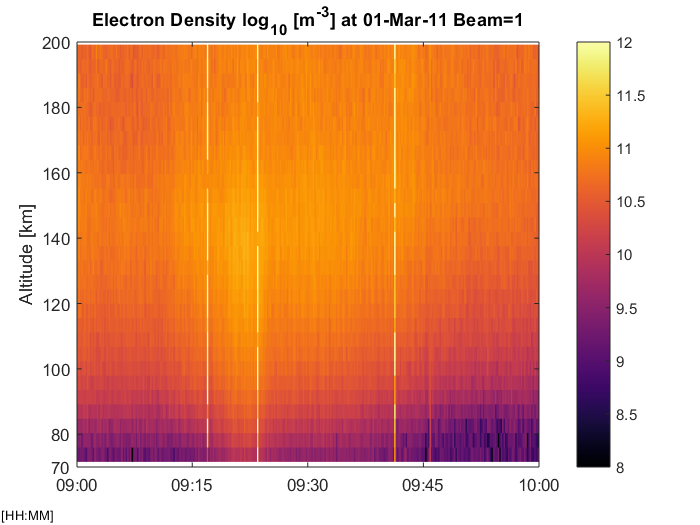

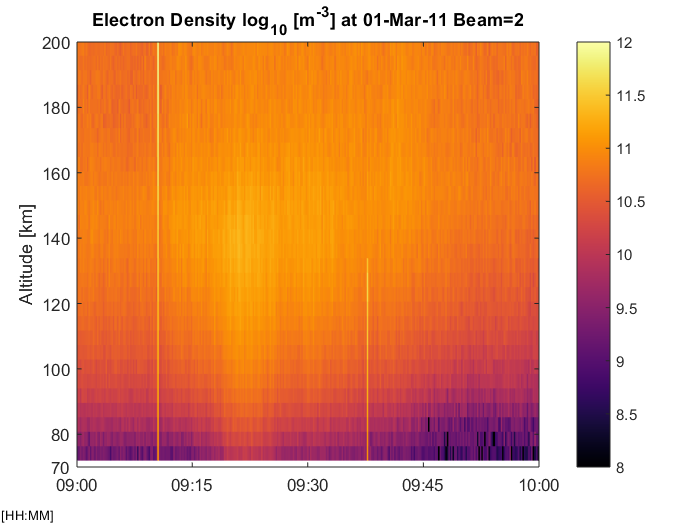

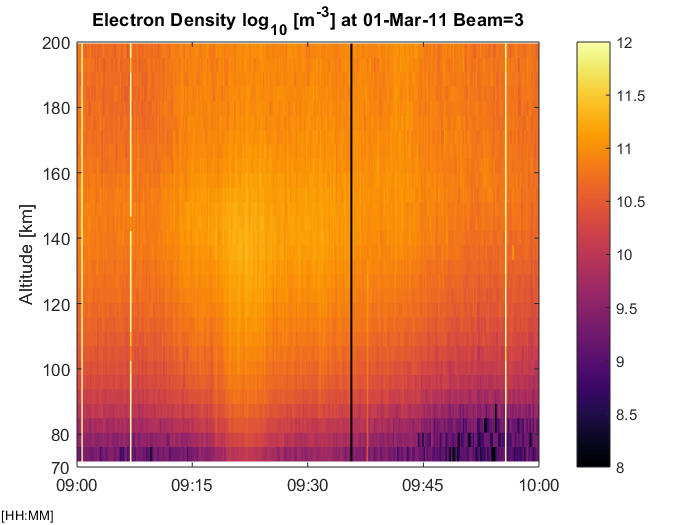

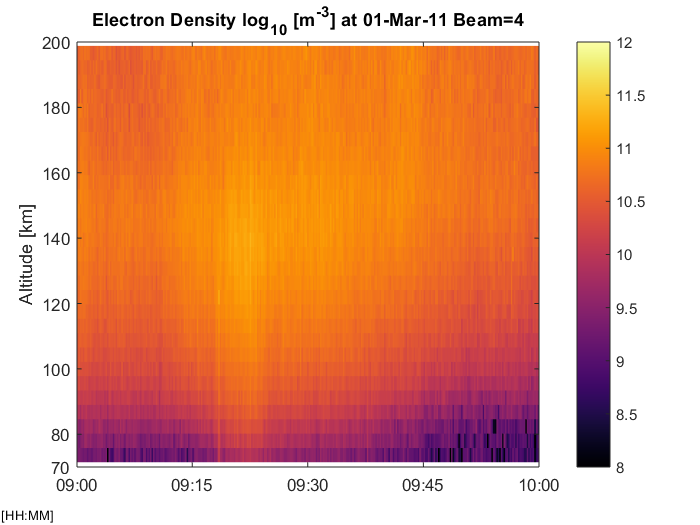

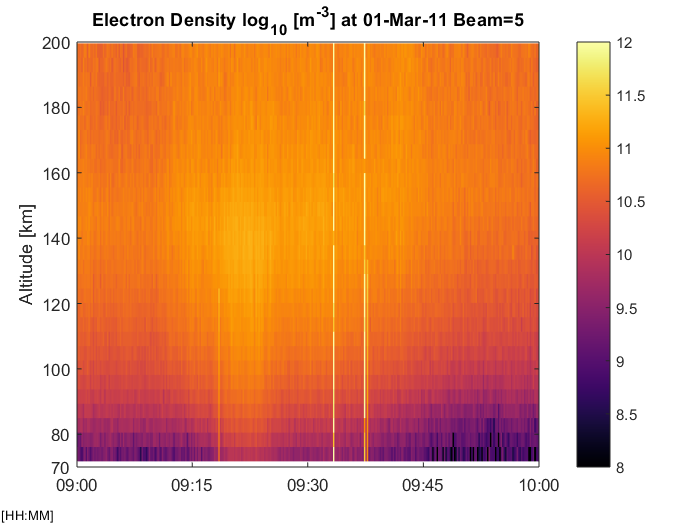

for iBeam = 1:1:5
    
    figure;
    colormap(inferno);
    dateMinStr = '1 Mar 2011 9:00';
    dateMaxStr = '1 Mar 2011 10:00';
    minAltNo = find_altitude(data.altitude(:,iBeam),70);
    maxAltNo = find_altitude(data.altitude(:,iBeam),200);
    plot_2D_time_series(data.time(1,:),data.altitude(minAltNo:maxAltNo,iBeam),log10(squeeze(data.electronDensity(minAltNo:maxAltNo,iBeam,:))),0.25,1,dateMinStr, dateMaxStr);
    colorbar;
    caxis([8 12]);
    title(['Electron Density log_1_0 [m^-^3] at 01-Mar-11 Beam=',num2str(iBeam)]);
    set(gca,'YTick',[70 80 100 120 140 160 180 200]);
    set(gca,'YLim',[70 200]);
end

## 2. Plot Altitude Profile (Test)

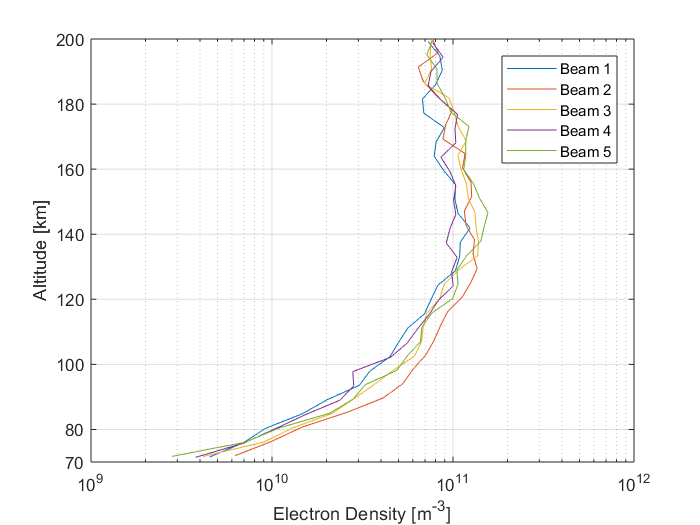

figure;
for iBeam = 1:1:5
    colormap(inferno);
    timeStr = '1 Mar 2011 9:30';
%     timeNo = find_time(data.time(1,:),timeStr);
    minAltNo = find_altitude(data.altitude(:,iBeam),70);
    maxAltNo = find_altitude(data.altitude(:,iBeam),200);
%     plot_2D_time_series(data.time(1,:),data.altitude(minAltNo:maxAltNo,iBeam),log10(squeeze(data.electronDensity(minAltNo:maxAltNo,iBeam,:))),0.25,1,dateMinStr, dateMaxStr);
    plot_1D_time_slice(data.time(1,:),data.altitude(minAltNo:maxAltNo,iBeam),data.electronDensity(minAltNo:maxAltNo,iBeam,:),timeStr,1);
    hold on;
end
legend('Beam 1','Beam 2','Beam 3', 'Beam 4', 'Beam 5');
%     title(['Electron Density log_1_0 [m^-^3] at 01-Mar-11 Beam=',num2str(iBeam)]);
    set(gca,'YTick',[70 80 100 120 140 160 180 200]);
    set(gca,'YLim',[70 200]);

## 3. MSIS Test

time = data.time(1,1:100:end);
latitude = 65.12;
longitude = -147.47;
alt = 80;

[D, T, F10_7_USED, AP_USED] = msis(time, latitude, longitude, alt);
nO      = D(:,1);
nN2     = D(:,2);
nO2     = D(:,3);
density = D(:,4);

Studying how the MSIS density varies through time at PFISR location. 

**MSIS Test Plots**

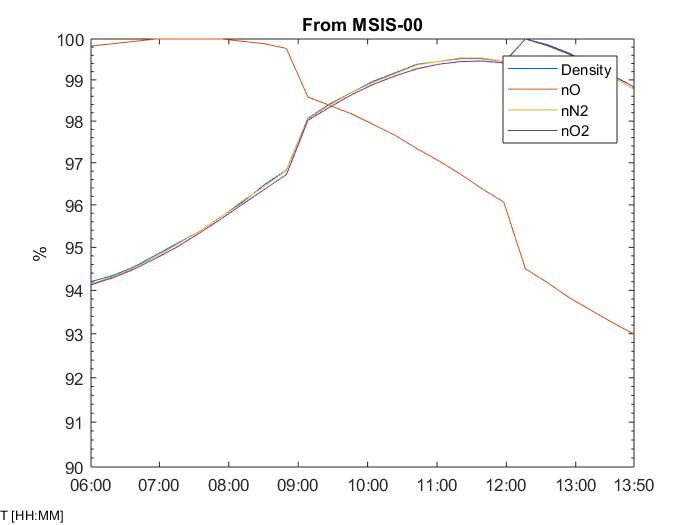


figure;
semilogy(time,100*density/max(density));
hold on;
semilogy(time,100*nO/max(nO));
hold on;
semilogy(time,100*nN2/max(nN2));
hold on;
semilogy(time,100*nO2/max(nO2));
hold on;
label_time_axis(time, true, 1);
ylim([90,100]);
ylabel('%')
legend('Density','nO','nN2','nO2');
title('From MSIS-E-90');

## 4. Energy Inversion Forward model Test


time = data.time(1,1000);
alt = (60:1:200)';
energyBin = (1:1:1000)'*1000; % 1 to 1000 keV 
[D, T, F10_7_USED, AP_USED] = msis(time, latitude, longitude, alt);
nO      = D(:,1);
nN2     = D(:,2);
nO2     = D(:,3);
density = D(:,4);


Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 93)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFile
 

## Plot the forward model

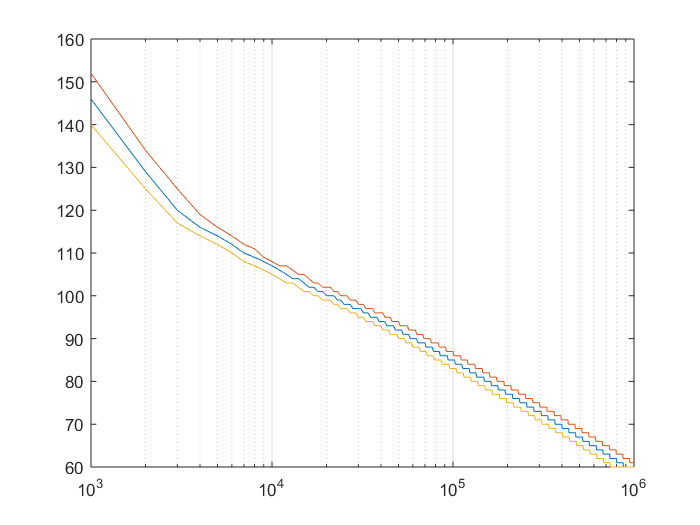

ans = 1

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 111)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFil

ans = 1.3195

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 111)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFil

ans = 0.7579

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 111)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFil

figure;
for i=1:1:3
    switch i
        case 1
            density1 = density;
            nN2_1 = nN2;
            nO2_1 = nO2;
        case 2
            density1=density*2^(2/5);   % Temperature halved & adiabatic atmosphere
            nN2_1 = nN2/10;
            nO2_1 = nO2/10;
        case 3
            density1=density*0.5^(2/5);  % Temperature is doubled
            nN2_1 = nN2*10;
            nO2_1 = nO2*10;
    end
density1(1)/density(1)
[A] = ionization_profile_matrix(alt,energyBin,nO,nN2,nO2,density1,1); % [cm-1 eV]

% Converting to SI units
A = (100)*A; %[m-1 eV]

[maxAVal,maxAltIndex] = max(A);
 semilogx(energyBin,alt(maxAltIndex));
 hold on;
end

legend('T* = T', 'T* = T/2', 'T* = 2T');